mutated=[3,6,9,10,14,15,18,21,28:30]; %+30
unmutated=[1,2,4,5,7,11,13,16,17,19,20,22:26];
nr=[8,27];

patients=[1:11,13:30];
%inputFolder='/Figures/03_22/';
inputFolder='/Figures/03_29/';
sheet=1;
%inputFolder='/Figures/'

%outputFolder='/Figures/03_22/paramAnalysis/burger_model/';
outputFolder=strcat("/Figures/03_25_analysis/");
outputTableName='paramsAll_extendedWithChars_sep_3tss_s';
compCriteria="bic";
minOrMax="min";
threshold=0;

%model whose parameters shall be analysed.
%enter -1 if the best model within the specified folder should be used.
model_un=1;
pre_model=[-1];
model_mut=1;
model=0;

pre_therapy=false;

% get bestModeltableChars
if model==-1
    BestModels=getBestModelsWithParams(patients,inputFolder,compCriteria,minOrMax,threshold);
else
    if pre_therapy
        BestModels_mut=getModelParams_pre(mutated,inputFolder,model_mut,pre_model,sheet);
        BestModels_unmut=getModelParams_pre(unmutated,inputFolder,model_un,pre_model,sheet);
        BestModels_nr=getModelParams_pre(nr,inputFolder,model_mut,pre_model,sheet);
    else
        BestModels_mut=getModelParams(mutated,inputFolder,model_mut,sheet);
        BestModels_unmut=getModelParams(unmutated,inputFolder,model_un,sheet);
        BestModels_nr=getModelParams(nr,inputFolder,model_mut,sheet);
    end
    BestModels=[BestModels_mut;BestModels_unmut;BestModels_nr];
end

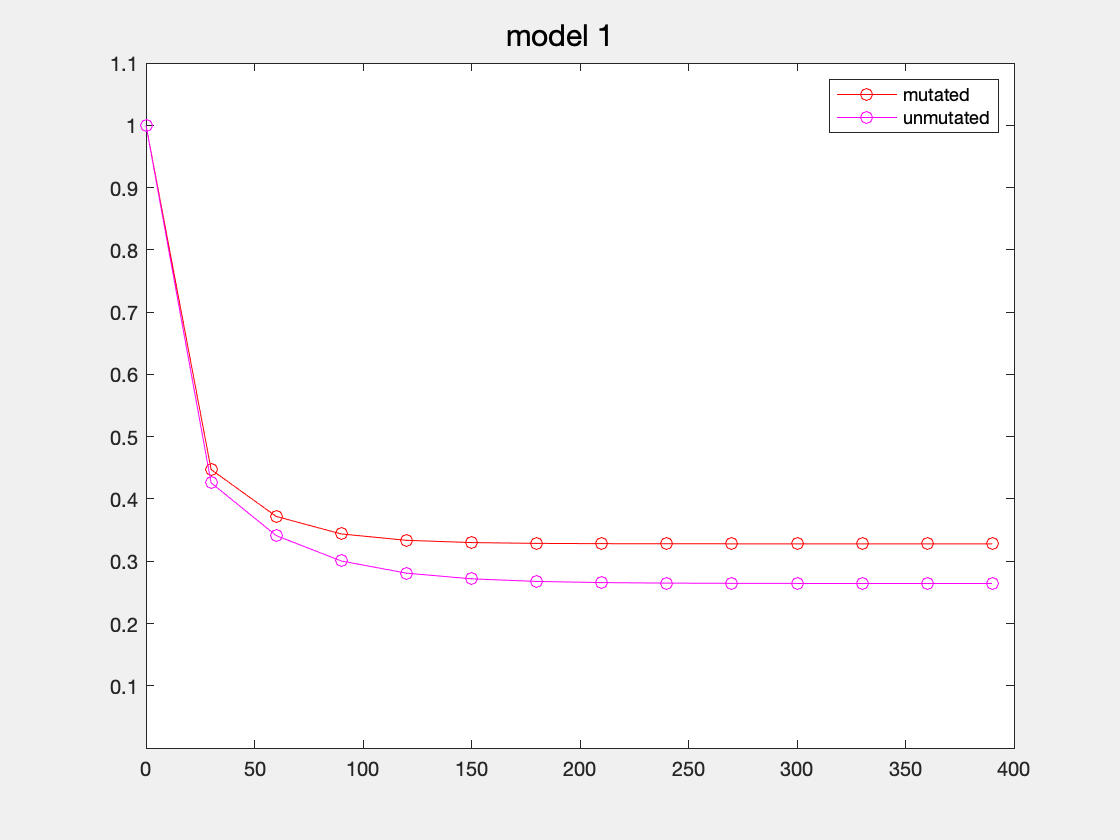

names=getVarNames(1);

tssTable=BestModels;
for modell=[1]

    figure("Visible","on");
    sgtitle("model "+modell);
    tspanx=0:30:390;
    tspany=[];
    X_plot=[];
    for pat=mutated
        parameters=tssTable(tssTable.model==modell&tssTable.ACC==pat,names(getRelevantParams(modell))).Variables;
        [x,~,~]=solution(parameters,tspanx,[],[],modell);
        %x=x./x(1);
        x_scaled=x.^(2/3);
        x_toplot=x_scaled./x_scaled(1);
        %x_toplot=x_scaled;
        X_plot=[X_plot;x_toplot];            
    end
    x_mut=mean(X_plot,1);
    X_plot=[];
    for pat=unmutated
        parameters=tssTable(tssTable.model==modell&tssTable.ACC==pat,names(getRelevantParams(modell))).Variables;
        [x,~]=solution(parameters,tspanx,[],[],modell);
        %x=x./x(1);
        x_scaled=x.^(2/3);
        x_toplot=x_scaled./x_scaled(1);
        %x_toplot=x_scaled;
        X_plot=[X_plot;x_toplot];            
    end
    x_unmut=mean(X_plot,1);
    plot(tspanx,x_mut,'-o','Color','r');hold on;
    plot(tspanx,x_unmut,'-o','Color','m');hold on;
    legend('mutated','unmutated');
    ax=gca;
   % ax.YAxis.Scale="log";
    ax.YLim=[0.0001;1.1];

end

%BestModels.absolute_g=zeros(length(patients),1);
% for pat=patients
%     if BestModels(BestModels.ACC==pat,"model").Variables==1
%         BestModels(BestModels.ACC==pat,"absolute_g")=BestModels(BestModels.ACC==pat,"g");
%     else
%         BestModels(BestModels.ACC==pat,"absolute_g")={-BestModels(BestModels.ACC==pat,"g").Variables};
% 
%     end
% end

BestModels.PB_pre_0_rel=turnToRelativeCounts(BestModels.PB_0,BestModels.ACC);
BestModels.Blood_healthy_rel=turnToRelativeCounts(BestModels.Blood_healthy,BestModels.ACC);

if pre_therapy
    for i=1:length(patients)
        BestModels(i,"PB_0")={getPB_0(BestModels(i,"ACC").Variables,BestModels(i,["PB_pre_0","g_all_PB"]).Variables,BestModels(i,"model_pre").Variables)};
        
    end
end

%BestModels.absolute_bm_cells=getBMTotalCells(BestModels.BM_0,BestModels.ACC);
BestModels.alpha=BestModels.m_LT_PB+BestModels.d_LT;
%BestModels.influx_PB=BestModels.m_LT_PB+BestModels.m_BM_PB;
BestModels.influx_PB=BestModels.m_LT_PB;
BestModels.g_post=BestModels.influx_PB-BestModels.d_PB;
BestModels.fractLTBP=BestModels.LT_0./BestModels.PB_0;

%BestModels.totalTumorBurden=BestModels.PB_0+BestModels.LT_0+BestModels.BM_0;
BestModels.totalTumorBurden=BestModels.PB_0+BestModels.LT_0;
BestModels.fractPBall=BestModels.PB_0./(BestModels.totalTumorBurden);
BestModels.fractLTall=BestModels.LT_0./(BestModels.totalTumorBurden);
BestModels.fractBMall=BestModels.BM_0./(BestModels.totalTumorBurden);
BestModels.LT_cll=BestModels.LT_0-BestModels.LT_healthy;
BestModels.PB_cll=BestModels.PB_0-BestModels.Blood_healthy;
BestModels.LT_shrinkage=BestModels.LT_healthy./BestModels.LT_0;
BestModels.tp_y_max=zeros(length(patients),1);
%BestModels.tp_z_max=zeros(length(patients),1);
BestModels.y_max=zeros(length(patients),1);
BestModels.y_max_rel=zeros(length(patients),1);
BestModels.y_max_perc=zeros(length(patients),1);
BestModels.y_max_rel_perc=zeros(length(patients),1);
%BestModels.z_max=zeros(length(patients),1);

BestModels.lymph_duration=zeros(length(patients),1);
%BestModels.lymph_duration_bm=zeros(length(patients),1);
%BestModels.z_max_perc=zeros(length(patients),1);

%BestModels.z_three_years=zeros(length(patients),1);
BestModels.y_three_years_rel=zeros(length(patients),1);

tspan=[0:0.1:1100,3000];
%names=getVarNames(model);
%names=names(getRelevantParams(model));
for pat=patients
%      if ~isempty(find(unmutated==pat, 1))
%         model=model_un;
%     else
%        model=model_mut;
%      end
    model=BestModels(BestModels.ACC==pat,"model").Variables;
    names=getVarNames(model);
    names=names(getRelevantParams(model));
    params=BestModels(BestModels.ACC==pat,names);
%     if ~isempty(find(unmutated==pat, 1))
%         model=model_un;
%     else
%        model=model_mut;
%     end
    [~,y,z ]=solution(params.Variables,[],tspan,tspan,model);
    BestModels(BestModels.ACC==pat,"tp_y_max")={tspan(y==max(y))};
    BestModels(BestModels.ACC==pat,"y_max")={max(y)};
    BestModels(BestModels.ACC==pat,"y_max_rel")={turnToRelativeCounts(max(y),pat)};
    BestModels(BestModels.ACC==pat,"y_max_perc")={(max(y)-y(1))/y(1)};
 
    
    BestModels(BestModels.ACC==pat,"y_max_rel_perc")={(turnToRelativeCounts(max(y),pat)-turnToRelativeCounts(y(1),pat))/turnToRelativeCounts(y(1),pat)};
    lymphEnd=min(tspan(y-y(1)<0));
    if isempty(lymphEnd)
        lymphEnd=-1;
    end
    BestModels(BestModels.ACC==pat,"lymph_duration")={lymphEnd};    
    
%     BestModels(BestModels.ACC==pat,"tp_z_max")={tspan(z==max(z))};
%     BestModels(BestModels.ACC==pat,"z_max")={max(z)};
%     BestModels(BestModels.ACC==pat,"lymph_duration_bm")={min(tspan(z-z(1)<0))};
%     BestModels(BestModels.ACC==pat,"z_max_perc")={(max(z)-z(1))/z(1)};
%     
%     BestModels(BestModels.ACC==pat,"z_three_years")={z(tspan==3000)/estimateBMCells(pat)};
    BestModels(BestModels.ACC==pat,"y_three_years_rel")={turnToRelativeCounts(y(tspan==3000),pat)};

    
end

writetable(BestModels,strcat(pwd,outputFolder,outputTableName,'.xlsx'));


%getChars
Chars=getChars(patients);
Chars.age_Ibrutinib=Chars.FAMPDATE_Ibrutinib_-Chars.DayOfBirth;

Chars.mutZap=zeros(size(Chars,1),1);
%mut+Zap combine:
%mutZap:
%   ==0 : iff MS unmutated and ZAP negative
%   ==1 : iff MS unmutated and ZAP positive
%   ==2 : iff MS mutated and ZAP negative
%   ==3 : iff MS mutated and ZAP positive
%   ==4 : iff MS NR
for i=1:size(Chars,1)
    if Chars.MS_decoded(i)==0 && Chars.ZAPnumb(i)==1
        Chars.mutZap(i)=1;
    elseif Chars.MS_decoded(i)==1
        if Chars.ZAPnumb(i)==0
            Chars.mutZap(i)=2;
        else
            Chars.mutZap(i)=3;
        end
    elseif Chars.MS_decoded(i)==2
        Chars.mutZap(i)=4;
    end
end

tableChars=join(BestModels,Chars);
writetable(tableChars,strcat(pwd,outputFolder,outputTableName,'WithChars.xlsx'));

%firstCriteriaNamesOne=["lymph_duration","tp_y_max","y_max","y_max_rel","y_max_perc","lymph_duration_bm","tp_z_max","z_max","z_max_perc","z_three_years","y_three_years_rel"];
firstCriteriaNamesOne=BestModels.Properties.VariableNames([36:42,44:end]);
if pre_therapy
    firstCriteriaNames=[names,"PB_pre_0","g_all_PB",firstCriteriaNamesOne];
else
    firstCriteriaNames=[names,firstCriteriaNamesOne];
end
%firstCriteriaNames=["d_PB","LT_0","LT_healthy","m_BM_PB","g_all_PB","lymph_duration","tp_y_max","y_max_rel","y_max_perc"];
%firstCriteriaNames=["g_all_PB"];
secondCriteriaNames=["MS_decoded","ZAP70MDA_IHC_"];
%firstCriteriaNames=firstCriteriaNames([3:8]);
%firstCriteriaNames=firstCriteriaNames([11,13:14]);
%secondCriteriaNames=["MS_decoded"];
%secondCriteriaNames=firstCriteriaNames;
% S = vartype('numeric');
% secondCriteriaNames=Chars(:,S).Properties.VariableNames;

%secondCriteriaNames=secondCriteriaNames([6:10,12,13,21,25,end]);
xscale="log";
yscale="log";
FirstTable=BestModels;
%SecondTable=Chars;
SecondTable=Chars;


% for paramName = firstCriteriaNames
%     for charName = secondCriteriaNames
%         paramMut=[];
%         paramUnmut=[];
%         paramNr=[];
% 
%         charMut=[];
%         charUnmut=[];
%         charNr=[];
% 
%         for patient = mutated
%             paramMut=[paramMut,FirstTable(FirstTable.ACC==patient,paramName).Variables];
%             charMut=[charMut,SecondTable(SecondTable.ACC==patient,charName).Variables];
%         end
% 
% 
%         for patient = unmutated
% 
%             paramUnmut=[paramUnmut,FirstTable(FirstTable.ACC==patient,paramName).Variables];
%             charUnmut=[charUnmut,SecondTable(SecondTable.ACC==patient,charName).Variables];
%         end
% 
%         for patient = nr
% 
%             paramNr=[paramNr,FirstTable(FirstTable.ACC==patient,paramName).Variables];
%             charNr=[charNr,SecondTable(SecondTable.ACC==patient,charName).Variables];
% 
%         end
%         
% %         indMut=paramMut>0;
% %         indUnmut=paramUnmut>0;
% %         indNr=paramNr>0;
% %       
%     %enable logscale -> set 0 to e-15
%     
% %         charMut(paramMut==0)=[];
% %         charUnmut(paramUnmut==0)=[];
% %         charNr(paramNr==0)=[];
%         
%         paramMut(paramMut==0)=1e-15;
%         paramUnmut(paramUnmut==0)=1e-15;
%         paramNr(paramNr==0)=1e-15;
%         
%         charMut(charMut==0)=1e-15;
%         charUnmut(charUnmut==0)=1e-15;
%         charNr(charNr==0)=1e-15;
% 
% %         
% %         charMut=charMut(indMut);
% %         charUnmut=charUnmut(indUnmut);
% %         charNr=charNr(indNr);
%         
% 
% 
%         sz = 60;
% 
%         figure('Visible',"on");
% 
%         plotTitle=sgtitle('Param Analysis - '+string(charName)+'-->'+string(paramName));
% 
%         s=scatter(charMut, paramMut,80,'filled','s','MarkerFaceColor',[0.6350 0.0780 0.1840]); hold on;
%         scatter(charUnmut, paramUnmut,80,'filled','^','MarkerFaceColor',[0 0.4470 0.7410]); hold on;
%        % scatter(charNr, paramNr,80,'*','MarkerEdgeColor',[0.1290 0.6940 0.1250]); hold on;
%         set(gca, 'yscale',yscale);
%         set(gca, 'xscale',xscale);
%         %ylim([0.05 10]);
%         xlabel(charName);
%         ylabel(paramName);
% 
%         fig = gca;
%         fig.YColor='black';
% 
% 
%         f=gcf;
%         
%         
%         [h, icons]=legend('MUTATED', 'UNMUTATED','Fontsize',18); 
%         plot([-0.15,0.15],[mean(paramUnmut),mean(paramUnmut)],'--'); hold on;
%         plot([0.85,1.15],[mean(paramMut),mean(paramMut)],'--'); hold on;
%         interest=input("Is this plot interesting? - 'yes' or 'no' or 'del'");
%         
%         if interest ~= "del"
%             savefig(f,strcat(pwd,outputFolder,interest,"/",plotTitle.String),'compact');
%         end
%         close(f);
%     end
% end

% reg=table;
% for i=1:length(firstCriteriaNames)
%     reg{:,firstCriteriaNames(i)}=zeros(2*length(firstCriteriaNames),1);
%     logg=strcat(firstCriteriaNames(i),"_logged");
%     reg{:,logg}=zeros(2*length(firstCriteriaNames),1);
%     
% end
% reg.Properties.RowNames=reg.Properties.VariableNames;
% for parOne=firstCriteriaNames
%     for parTwo=firstCriteriaNames
%         
%         oneLogged=strcat(parOne,"_logged");
%         twoLogged=strcat(parTwo,"_logged");
%         
%         mdl=fitlm(BestModels{:,parOne},BestModels{:,parTwo});
%         reg(parOne,parTwo)={mdl.Coefficients.pValue(end)};
%         
%         mdl=fitlm(BestModels{:,parOne},log10(BestModels{:,parTwo}));
%         reg(parOne,twoLogged)={mdl.Coefficients.pValue(end)};
%         
%         mdl=fitlm(log10(BestModels{:,parOne}),BestModels{:,parTwo});
%         reg(oneLogged,parTwo)={mdl.Coefficients.pValue(end)};
%         
%         mdl=fitlm(log10(BestModels{:,parOne}),log10(BestModels{:,parTwo}));
%         reg(oneLogged,twoLogged)={mdl.Coefficients.pValue(end)};
%     end
% end

%writetable(reg,strcat(pwd,outputFolder,"regression.xlsx"));

mut_t=table(zeros(2,length(firstCriteriaNames)*2));
mut_t=table;
for i=1:length(firstCriteriaNames)
    mut_t{:,firstCriteriaNames(i)}=zeros(2,1);
    logg=strcat(firstCriteriaNames(i),"_logged");
    mut_t{:,logg}=zeros(2,1);
end
zap_t=mut_t;
mut_rank_ks=table;
for i=1:length(firstCriteriaNames)
    mut_rank_ks{:,firstCriteriaNames(i)}=zeros(2,1);
end

zap_rank_ks=mut_rank_ks;


for param=firstCriteriaNames

    [~,p]=ttest2(tableChars(tableChars.MS=="MUTATED",param).Variables,tableChars(tableChars.MS=="UNMUTATED",param).Variables);
    mut_t(1,param)={p};
    %mut_t(1,logg)={
    [~,p]=ttest2(log(tableChars(tableChars.MS=="MUTATED",param).Variables),log(tableChars(tableChars.MS=="UNMUTATED",param).Variables));
    mut_t(1,strcat(param,"_logged"))={p};
    [~,p]=ttest2(tableChars(tableChars.MS=="MUTATED",param).Variables,tableChars(tableChars.MS=="UNMUTATED",param).Variables,"Vartype","unequal");
    mut_t(2,param)={p};
    [~,p]=ttest2(log(tableChars(tableChars.MS=="MUTATED",param).Variables),log(tableChars(tableChars.MS=="UNMUTATED",param).Variables),"Vartype","unequal");
    mut_t(2,strcat(param,"_logged"))={p};
%[h,p]=ttest2(log(tableChars(tableChars.MS=="MUTATED",param).Variables),log(tableChars(tableChars.MS=="UNMUTATED",param).Variables),"Vartype","unequal")

end

for param=firstCriteriaNames
        mut_rank_ks(1,param)={ranksum(tableChars(tableChars.MS=="MUTATED",param).Variables,tableChars(tableChars.MS=="UNMUTATED",param).Variables)};
end

for param=firstCriteriaNames
    [~,p]=kstest2(tableChars(tableChars.MS=="MUTATED",param).Variables,tableChars(tableChars.MS=="UNMUTATED",param).Variables);
    mut_rank_ks(2,param)={p};
end

for param=firstCriteriaNames

    [~,p]=ttest2(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables,tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables);
    zap_t(1,param)={p};
    [~,p]=ttest2(log(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables),log(tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables));
    zap_t(1,strcat(param,"_logged"))={p};
    [~,p]=ttest2(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables,tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables,"Vartype","unequal");
    zap_t(2,param)={p};
    [~,p]=ttest2(log(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables),log(tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables),"Vartype","unequal");
    zap_t(2,strcat(param,"_logged"))={p};
end

for param=firstCriteriaNames

    zap_rank_ks(1,param)={ranksum(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables,tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables)};
end

for param=firstCriteriaNames

    [~,p]=kstest2(tableChars(tableChars.ZAP70MDA_IHC_=="POS",param).Variables,tableChars(tableChars.ZAP70MDA_IHC_=="NEG",param).Variables);
    zap_rank_ks(2,param)={p};
end

writetable(mut_t,strcat(pwd,outputFolder,"ttest_mutation.xlsx"));
writetable(mut_rank_ks,strcat(pwd,outputFolder,"ranksum_kolg_mutation.xlsx"));
writetable(zap_t,strcat(pwd,outputFolder,"ttest_zap.xlsx"));
writetable(zap_rank_ks,strcat(pwd,outputFolder,"ranksum_kolg_zap.xlsx"));